# **Solving ODEs Numerically In MATLAB**

06.12.2023

Numerical solutions to ordinary differential equations (ODEs) are useful when exact analytical solutions are difficult or impossible to obtain. ODEs can be solved numerically by using built-in ODE solvers in MATLAB. The following example discusses the usage of these solvers.

## Mass - Spring - Damper System

### **Time Response**

 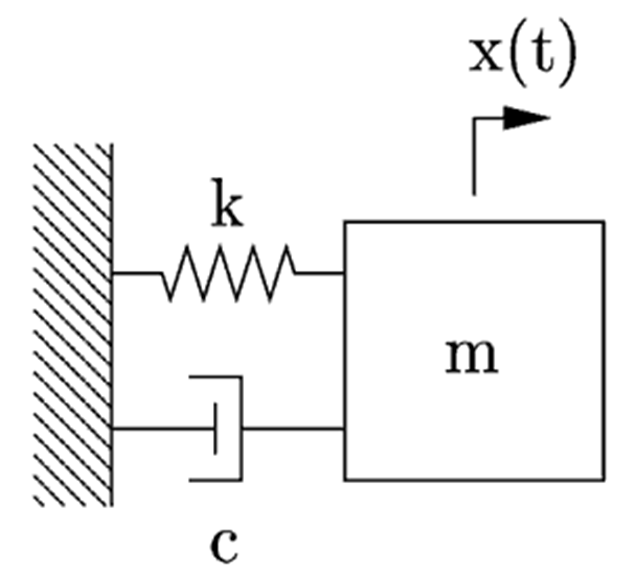                     **Equation of Motion : **$m\ddot{x} +c\dot{x} +\textrm{kx}=f\left(t\right)$

If f(t) is a step function such that $f\left(t\right)=F$ for $t>0$ and $x\left(0\right)=x_0 \;,\dot{x} \left(0\right)=v_0$ are initial conditions, then analytical solution to this ODE can be given as 


$$\begin{array}{l}
x\left(t\right)=\left\lbrace \begin{array}{l}
\frac{F}{k}\left\lbrace 1-e^{-\zeta \omega_n t} \left(\cos \left(\omega_d t\right)+\frac{\zeta }{\sqrt{1-\zeta^2 }}\sin \left(\omega_d t\right)\right)\right\rbrace \;+\;\sqrt{x_0^2 +{\left(\frac{\zeta \;\omega_n x_0 +v_0 }{\omega_d }\right)}^2 }e^{-\zeta \;\omega_n t} \cos \left(\omega_d t-\tan^{-1\;} \frac{\zeta \;\omega_n x_0 +v_0 }{x_0 \omega_d }\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;\zeta <1\\
\frac{F}{k}\left\lbrace 1-e^{-\zeta \omega_n t} \left(1+\omega_n t\right)\right\rbrace \;+\left\lbrace \left(\zeta \;\omega_n x_0 +v_0 \right)t+x_0 \right\rbrace e^{-\zeta \;\omega_n t} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;\zeta =1\\
\frac{F}{k}\left\lbrace 1+\frac{\omega_n }{2\sqrt{\zeta^2 -1}}\left(\frac{e^{-\left(\zeta +\sqrt{\zeta^2 -1}\right)\omega_n t} }{\zeta +\sqrt{\zeta^2 -1}}-\frac{e^{-\left(\zeta -\sqrt{\zeta^2 -1}\right)\omega_n t} }{\zeta -\sqrt{\zeta^2 -1}}\right)\right\rbrace +\left(x_0 \cosh \left(\omega_n \sqrt{\zeta^2 -1}t\right)+\frac{\zeta \;\omega_n x_0 +v_0 }{\omega_n \sqrt{\zeta^2 -1}}\sinh \left(\omega_n \sqrt{\zeta^2 -1}t\right)\right)\;\;\;\;\textrm{for}\;\zeta >1\;
\end{array}\;\;\right.\\
\;\;\;\textrm{where}\;\zeta =\frac{c}{2\sqrt{\textrm{km}}}\;,\omega_n =\sqrt{\frac{k}{m}}\;,\omega_d =\omega_n \sqrt{1-\zeta^2 }\;\ldotp 
\end{array}$$
 

Equation of motion is written in state space form to define the ODE in MATLAB as a local function at the end of the code. The function can also be defined in a seperate file.

                                                               
$$x_1 =x\;,\;\;\;x_2 =\dot{x} \;,\;\;\;\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{k}{m} & -\frac{c}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}
\end{array}\right\rbrack f\left(t\right)\ldotp$$


MATLAB provides several built-in solvers for numerical solutions of ODEs. The table below serves as a guide for selecting the appropriate solver in MATLAB.

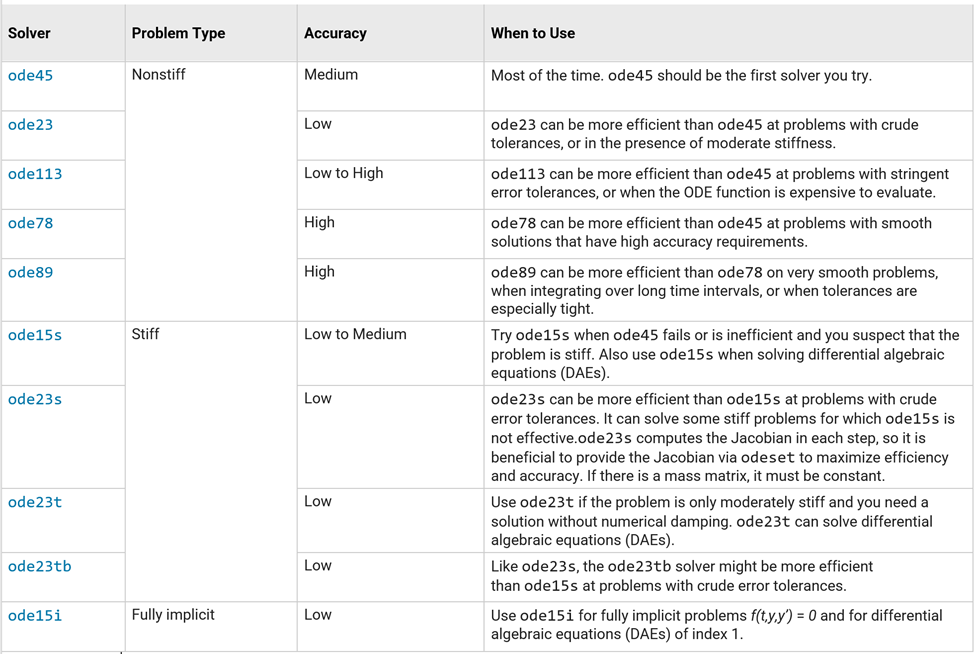

ode45 is the most commonly used ODE solver in MATLAB. It can be used to solve the ODE that describes the mass spring damper system above as follows.

m = 25;
c = 50;
k = 100;
f = 16;
tspan = [0 5];
y0 = [0 0.02];

ODE solver parameters can be set with odeset function. Error tolerance and step size are most crucial parameters for ODE solvers. A relative or absolute error tolerance target can be defined so that the solver continues until the following condition is met.

`|e(i)| <= max(RelTol*abs(y(i)),AbsTol(i))`

`ODE solvers in MATLAB uses variable step size. Initial and maximum step size can be defined for the solver using odeset function.`

opts = odeset('RelTol',0.00419,'AbsTol',0.00551,'InitialStep',0.628301,'MaxStep',1.71);
init_step = opts.InitialStep;
[t,y] = ode45(@(t,y)msd(t,y,m,c,k,f,"step",init_step), tspan, y0,opts);

` Numerical solution by ode45 can be compared to the analytical solution as follows.`

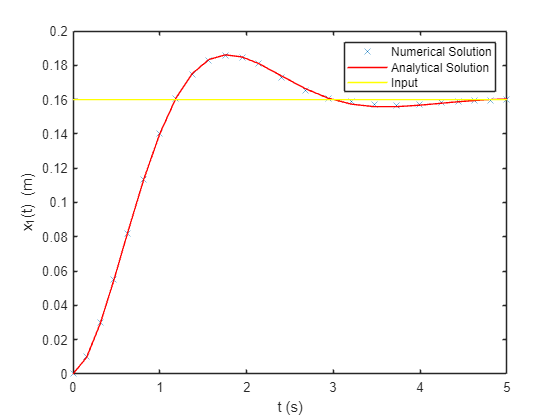

zeta = c/(2*sqrt(k*m)); w_n = sqrt(k/m); w_d = w_n*sqrt(1-zeta^2);
x0 = y0(1); v0 = y0(2);

if zeta < 1
    y_a = f/k*(1-exp(-zeta*w_n*t).*(cos(w_d*t) + zeta/(sqrt(1-zeta^2))*sin(w_d*t))) + sqrt(x0^2 + ((zeta*w_n*x0+v0)/w_d)^2).*exp(-zeta*w_n*t).*cos(w_d*t-atan2(zeta*w_n*x0+v0,x0*w_d));
elseif zeta == 1
    y_a = f/k*(1-exp(-zeta*w_n*t).*(1+w_n*t)) + ((zeta*w_n*x0+v0).*t +x0).*exp(-zeta*w_n*t);
else
    y_a = f/k*(1 + w_n/(2*sqrt(zeta^2-1))*(exp(-(zeta+sqrt(zeta^2-1)*w_n*t))/(zeta+sqrt(zeta^2-1)) - exp(-(zeta-sqrt(zeta^2-1)*w_n*t))/(zeta-sqrt(zeta^2-1)))) + x0*cosh(sqrt(zeta^2-1)*w_n*t) + (zeta*w_n*x0+v0)/(w_n*sqrt(zeta^2-1))*sinh(sqrt(zeta^2-1)*w_n*t);
end

in_step = f/k *ones(size(t,1)); 
plot(t,y(:,1),"x",t,y_a,"-r",t,in_step,"-y")
legend("Numerical Solution","Analytical Solution","Input" )
xlabel("t (s)")
ylabel("x_1(t) (m)")

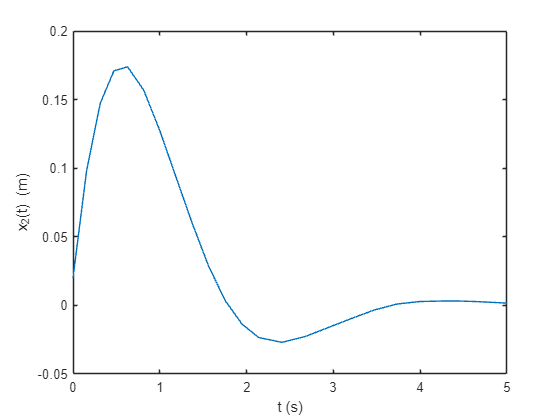

plot(t,y(:,2))
xlabel("t (s)")
ylabel("x_2(t) (m)")

There are ODE solvers other than ode45 in MATLAB. Following is a comprasion of solutions by different ODE solvers. 

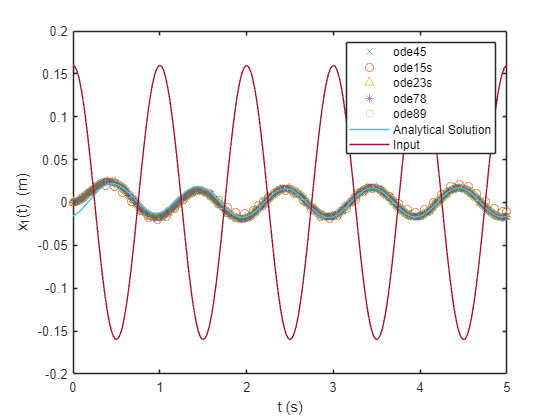

opts = odeset('RelTol',0.00816,'AbsTol',0.00551,'InitialStep',0.092301,'MaxStep',0.1);
[t_45,y_45] = ode45(@(t,y)msd(t,y,m,c,k,f,"sinus",init_step), tspan, y0,opts);
[t_15s,y_15s] = ode15s(@(t,y)msd(t,y,m,c,k,f,"sinus",init_step), tspan, y0,opts);
[t_23s,y_23s] = ode23s(@(t,y)msd(t,y,m,c,k,f,"sinus",init_step), tspan, y0,opts);
[t_78,y_78] = ode78(@(t,y)msd(t,y,m,c,k,f,"sinus",init_step), tspan, y0,opts);
[t_89,y_89] = ode89(@(t,y)msd(t,y,m,c,k,f,"sinus",init_step), tspan, y0,opts);

[y_i,t_i] = impulse(tf(1,[m c k]),5);
[y_r,t_r] = step(tf(f,[m c k 0]),5);
y_s = (f/sqrt((k-m*4*pi^2)^2 + (c*2*pi)^2))*cos(2*pi*t_45 - atan2(c*2*pi,k-m*4*pi^2));
if zeta < 1
    y_i = y_i + sqrt(x0^2 + ((zeta*w_n*x0+v0)/w_d)^2).*exp(-zeta*w_n*t_i).*cos(w_d*t_i-atan2(zeta*w_n*x0+v0,x0*w_d));
    y_r = y_r + sqrt(x0^2 + ((zeta*w_n*x0+v0)/w_d)^2).*exp(-zeta*w_n*t_r).*cos(w_d*t_r-atan2(zeta*w_n*x0+v0,x0*w_d));
    y_s = y_s + sqrt(x0^2 + ((zeta*w_n*x0+v0)/w_d)^2).*exp(-zeta*w_n*t_45).*cos(w_d*t_45-atan2(zeta*w_n*x0+v0,x0*w_d));
elseif zeta == 1
    y_i = y_i + ((zeta*w_n*x0+v0).*t_i +x0).*exp(-zeta*w_n*t_i);
    y_r = y_r + ((zeta*w_n*x0+v0).*t_r +x0).*exp(-zeta*w_n*t_r);
    y_s = y_s + ((zeta*w_n*x0+v0).*t_45 +x0).*exp(-zeta*w_n*t_45);
else
    y_i = y_i + x0*cosh(sqrt(zeta^2-1)*w_n*t_i) + (zeta*w_n*x0+v0)/(w_n*sqrt(zeta^2-1))*sinh(sqrt(zeta^2-1)*w_n*t_i);
    y_r = y_r + x0*cosh(sqrt(zeta^2-1)*w_n*t_r) + (zeta*w_n*x0+v0)/(w_n*sqrt(zeta^2-1))*sinh(sqrt(zeta^2-1)*w_n*t_r);
    y_s = y_s + x0*cosh(sqrt(zeta^2-1)*w_n*t_45) + (zeta*w_n*x0+v0)/(w_n*sqrt(zeta^2-1))*sinh(sqrt(zeta^2-1)*w_n*t_45);
end

in_step = f/k * ones(size(t,1)); 
in_ramp = f/k * t_45;
in_sinus = f/k * cos(2*pi*t_45);

plot(t_45,y_45(:,1),"x",t_15s,y_15s(:,1),"o",t_23s,y_23s(:,1),"^",t_78,y_78(:,1),"*",t_89,y_89(:,1),"square", t_45,y_s,"-",t_45,in_sinus,"-")
legend ("ode45","ode15s","ode23s","ode78","ode89","Analytical Solution","Input")
xlabel("t (s)")
ylabel("x_1(t) (m)")

### **Frequency Response**

Frequency response of the system can be obtained by bode() function in MATLAB.

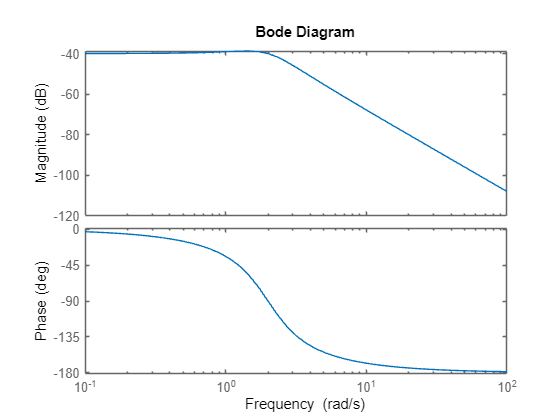

bode(tf(1,[m c k]))

### **Nonlinearity**

Although some simple systems can be modeled linearly, dynamic systems generally display nonlinear behavior. For example, the mass spring damper system above can be modeled with a nonlinear spring. Different spring models are shown in the figure below.

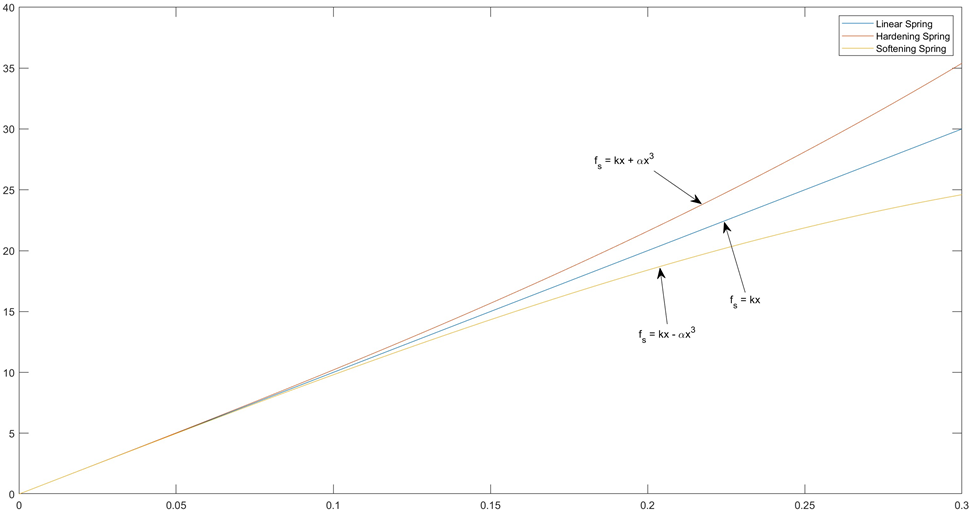

In the case of hardening spring, dynamic model of the system can be given as the following nonlinear ODE.

 **Equation of Motion : **$m\ddot{x} +c\dot{x} +\textrm{kx}+\alpha x^3 =f\left(t\right)$

Dynamic model can be written in the following form for implementation in MATLAB.


$$x_1 =x\;,\;\;\;x_2 =\dot{x} \;,\;\;\;\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_2 \\
-\frac{k}{m}x_1 -\frac{\alpha }{m}x_1^3 -\frac{c}{m}x_2 +\frac{f\left(t\right)}{m}
\end{array}\right\rbrack$$


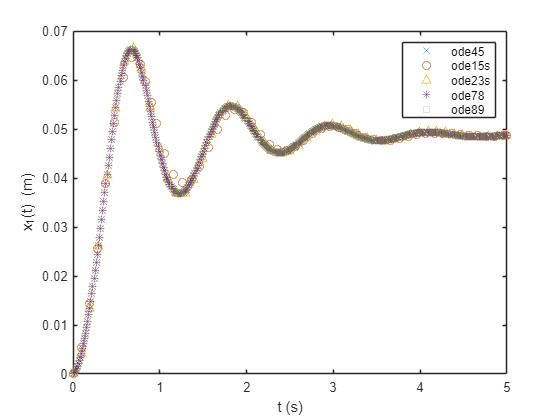

alpha = 96100;
opts = odeset('RelTol',0.00816,'AbsTol',0.00551,'InitialStep',0.092301,'MaxStep',0.1);
[t_45n,y_45n] = ode45(@(t,y)msd_nonlinear(t,y,m,c,k,alpha,f,"step",init_step), tspan, y0,opts);
[t_15sn,y_15sn] = ode15s(@(t,y)msd_nonlinear(t,y,m,c,k,alpha,f,"step",init_step), tspan, y0,opts);
[t_23sn,y_23sn] = ode23s(@(t,y)msd_nonlinear(t,y,m,c,k,alpha,f,"step",init_step), tspan, y0,opts);
[t_78n,y_78n] = ode78(@(t,y)msd_nonlinear(t,y,m,c,k,alpha,f,"step",init_step), tspan, y0,opts);
[t_89n,y_89n] = ode89(@(t,y)msd_nonlinear(t,y,m,c,k,alpha,f,"step",init_step), tspan, y0,opts);

plot(t_45n,y_45n(:,1),"x",t_15sn,y_15sn(:,1),"o",t_23sn,y_23sn(:,1),"^",t_78n,y_78n(:,1),"*",t_89n,y_89n(:,1),"square")
legend ("ode45","ode15s","ode23s","ode78","ode89")
xlabel("t (s)")
ylabel("x_1(t) (m)")

ODE function can be defined as follows.

function dydt = msd(t,y,m,c,k,f,input_type,init_step)
if input_type == "step"
    dydt(1,1) = y(2);
    dydt(2,1) = -k/m * y(1) - c/m * y(2) + f/m;
elseif input_type == "ramp"
    dydt(1,1) = y(2);
    dydt(2,1) = -k/m * y(1) - c/m * y(2) + f*t/m;
elseif input_type == "impulse"
    % if t <= init_step
    %     dydt(1,1) = y(2);
    %     dydt(2,1) = -k/m * y(1) - c/m * y(2) + (1/init_step)/m;
    % else 
    %     dydt(1,1) = y(2);
    %     dydt(2,1) = -k/m * y(1) - c/m * y(2);
    % end
    dydt(1,1) = y(2);
    dydt(2,1) = -k/m * y(1) - c/m * y(2) + (1/init_step)*(heaviside(t)-heaviside(t-init_step))/m;
elseif input_type == "sinus"
    dydt(1,1) = y(2);
    dydt(2,1) = -k/m * y(1) - c/m * y(2) + f*cos(2*pi*t)/m;
end

end

ODE function for the nonlinear ODE can be defined as follows.

function dydt = msd_nonlinear(t,y,m,c,k,alpha,f,input_type,init_step)
if input_type == "step"
    dydt(1,1) = y(2);
    dydt(2,1) = -k/m * y(1) - alpha/m * y(1)^3 - c/m * y(2) + f/m;
elseif input_type == "ramp"
    dydt(1,1) = y(2);
    dydt(2,1) = -k/m * y(1) - alpha/m * y(1)^3 - c/m * y(2) + f*t/m;
elseif input_type == "impulse"
    % if t <= init_step
    %     dydt(1,1) = y(2);
    %     dydt(2,1) = -k/m * y(1) - alpha/m * y(1)^3 - c/m * y(2) + (1/init_step)/m;
    % else 
    %     dydt(1,1) = y(2);
    %     dydt(2,1) = -k/m * y(1) - c/m * y(2);
    % end
    dydt(1,1) = y(2);
    dydt(2,1) = -k/m * y(1) - alpha/m * y(1)^3 - c/m * y(2) + (1/init_step)*(heaviside(t)-heaviside(t-init_step))/m;
elseif input_type == "sinus"
    dydt(1,1) = y(2);
    dydt(2,1) = -k/m * y(1) - alpha/m * y(1)^3 - c/m * y(2) + f*cos(2*pi*t)/m;
end

end

` Prepared by Research Assistant Muhammet Umut Danış at Istanbul Technical University.`

# `References`

`Ogata, K., 2002, Modern Control Engineering, 4th ed., Prentice Hall, Upper Saddle River, NJ.`

`Previous MAK4047E ODE Tutorials.`